# Advanced Protections, Homework 1

Leighton Clarke

April 5, 2018

## Part b (part a not included) - read CSV file into MATLAB and plot voltages and currents

Read the data file (must be headless and named EE537HW1.csv):

data = csvread('EE537HW1.csv');

Extract each column to define the time, voltage, and current arrays:

t = data(:,1);
Va = data(:,2);
Vb = data(:,3);
Vc = data(:,4);
Ia = data(:,5);
Ib = data(:,6);
Ic = data(:,7);

Plot voltages vs. time:

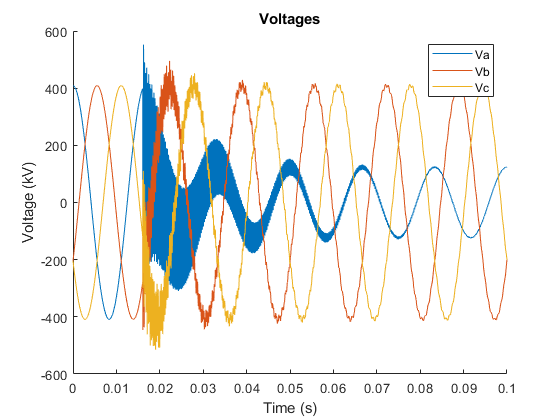

figure
xlabel('Time (s)')
ylabel('Voltage (kV)')
title('Voltages')
hold on
plot(t,Va/1000)
plot(t,Vb/1000)
plot(t,Vc/1000)
legend('Va', 'Vb', 'Vc')

Plot currents vs. time:

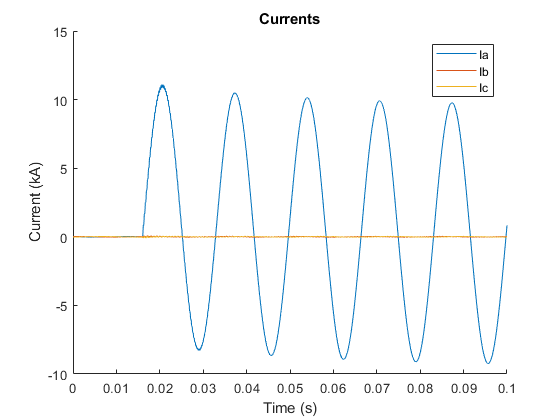

figure
xlabel('Time (s)')
ylabel('Current (kA)')
title('Currents')
hold on
plot(t,Ia/1000)
plot(t,Ib/1000)
plot(t,Ic/1000)
legend('Ia', 'Ib', 'Ic')

## Part c - plot frequency response of RC filter with cutoff frequency of 500Hz

Calculate the RC value for a simple analog RC filter with a cutoff frequency of 500Hz:


$$\mathrm{RC}=\frac{1}{2\pi f_c }$$


fc = 500;
RC = 1/(2*pi*fc)

RC = 3.1831e-04

The frequency response can be plotted by determining the filter's transfer function and sweeping the input frequency, or by using MATLAB's "bode" function. The transfer function is as follows:


$$H\left(s\right)=\frac{1}{s\mathrm{RC}+1}$$


The frequency sweeping method is shown first:

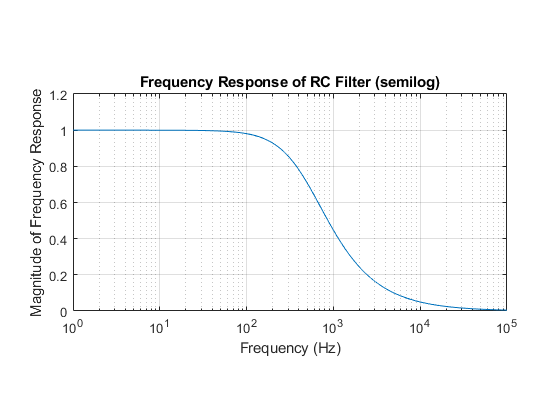

H1 = zeros(1,100000);
for k = 1:100000
    H1(k) = 1/(RC*1i*2*pi*k+1);
end

figure

semilogx(abs(H1));
ax = gca;
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Magnitude of Frequency Response';
ax.Title.String = 'Frequency Response of RC Filter (semilog)';
ax.XLim = [0 100000];
ax.YLim = [0 1.2];
ax.XGrid = 'on';
ax.YGrid = 'on';
pbaspect([2 1 1])

MATLAB's bode function yields the same results:

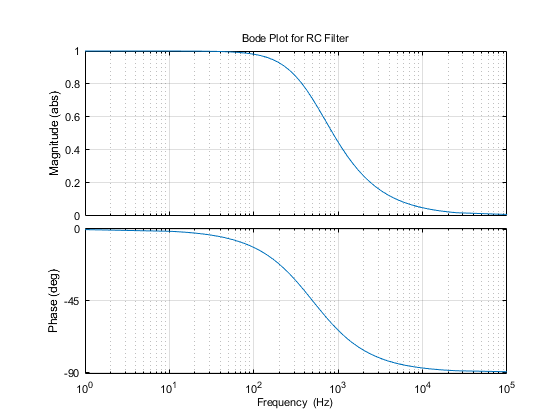

opts = bodeoptions;
opts.FreqUnits = 'Hz';
opts.MagUnits = 'abs';
opts.Grid = 'on';
opts.Title.String = 'Bode Plot for RC Filter';
opts.Xlim = [1 100000];
H2 = tf(1, [RC 1]);
bode(H2, opts)

It is not clear from the problem statement if the scale should be logarithmic or semi-logarithmic, so I have included a log-log plot of the frequency response as well:

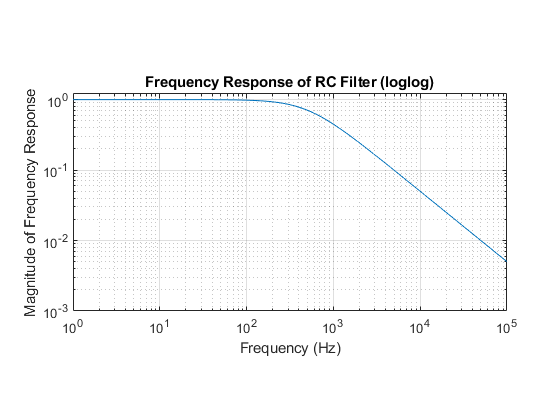

loglog(abs(H1))
ax = gca;
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Magnitude of Frequency Response';
ax.Title.String = 'Frequency Response of RC Filter (loglog)';
ax.XLim = [0 100000];
ax.YLim = [.001 1.2];
ax.XGrid = 'on';
ax.YGrid = 'on';
pbaspect([2 1 1])

## Part d - plot the output of the RC filter

First we calculate the secondary voltages using the provided PTR:

PTR = 4308;
Va2 = Va./PTR;
Vb2 = Vb./PTR;
Vc2 = Vc./PTR;

To plot the filter output, we use the following recursive equation:


$$v_k^{\left(o\right)} =\frac{\Delta t\cdot v_k^{\left(t\right)} +R\cdot C\cdot v_{k-1}^{\left(o\right)} }{\Delta t+R\cdot C}$$


An array can be populated with output values using a loop. We let the initial output value be zero.

Vo = zeros(length(t),1);
for k = 2:length(Vo)
    Vo(k)=((t(k)-t(k-1))*Va2(k)+RC*Vo(k-1))/((t(k)-t(k-1))+RC);
end

Finally, a side-by-side comparison of the filtered and unfiltered a-phase secondary voltages is shown below:

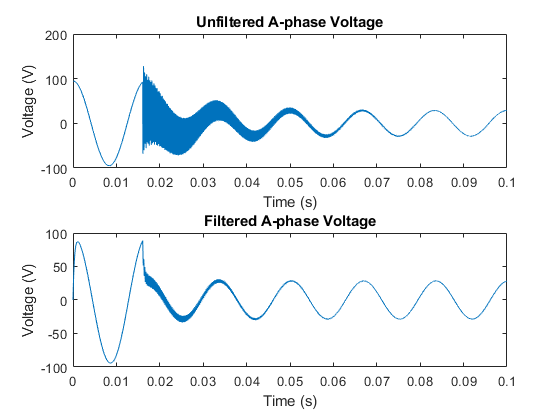

subplot(2,1,1);
plot(t,Va2)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Unfiltered A-phase Voltage')

subplot(2,1,2);
plot(t,Vo)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Filtered A-phase Voltage')

The filter clearly removes much of the high-frequency distortion from the secondary voltage signal.